# Understanding Network Predictions for Image Classification (UNPIC)

To start the UNPIC app you need two things: a trained network and an image datastore.

Load a trained network.

net = myTrainedNetwork;

Load image datastore that points to the test images.

testImages = myTestImages;

Skipping download, file already exists...
Skipping unzipping, file already unzipped...
Done.


To start the app, call `UNPIC` with the trained network and test images as input arguments.

UNPIC(net,testImages);

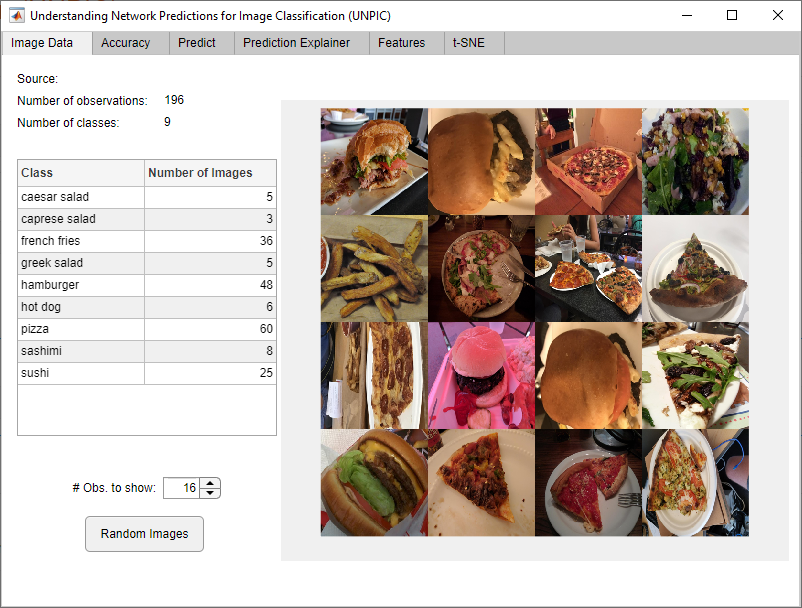

For more information on how to use the app to explore network predictions, see the attached examples.

- ExploreTrainedFoodClassificationNetwork.mlx (uses a pretrained network)

- VisualizeTrainedNetworkExample.mlx (trains a network from scratch)

## Supporting Functions

Supporting functions to help you get started with UNPIC.

### Load Trained Network

Load a pretrained food classification network. You can open the app with a pretrained network or a network you trained using `trainNetwork`. For an example showing how to train a classification network, see the attached example VisualizeTrainedNetworkExample.mlx.

function net = myTrainedNetwork()
data = load('trainedNet_Food.mat');
net = data.trainedNet;
end

### Load Test Images

This example uses a food classifaction data set. Download and extract the Example Food Image data set from [https://www.mathworks.com/supportfiles/nnet/data/ExampleFoodImageDataset.zip](https://www.mathworks.com/supportfiles/nnet/data/ExampleFoodImageDataset.zip).

function testImages = myTestImages

dataDir = fullfile(tempdir,"ExampleFoodImageDataset");
url = "https://ssd.mathworks.com/supportfiles/nnet/data/ExampleFoodImageDataset.zip";

if ~exist(dataDir,"dir")
    mkdir(dataDir);
end

downloadExampleFoodImagesData(url,dataDir);

Create an image datastore using the `imageDatastore` function.

imds = imageDatastore(dataDir, ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames');

imds.Labels = categorical(replace(string(imds.Labels),"_"," "));

Split the data into training and validation sets.

rng default
[imdsTrain, imdsVal] = splitEachLabel(imds,0.8,0.2,'randomized');

Use the validation split for the test images.

testImages = imdsVal;
end